# Mathematical foundation

clear

## Functions R to R and gradient

Function

f = @(x, y) x.^2 + y.^2;

Plot

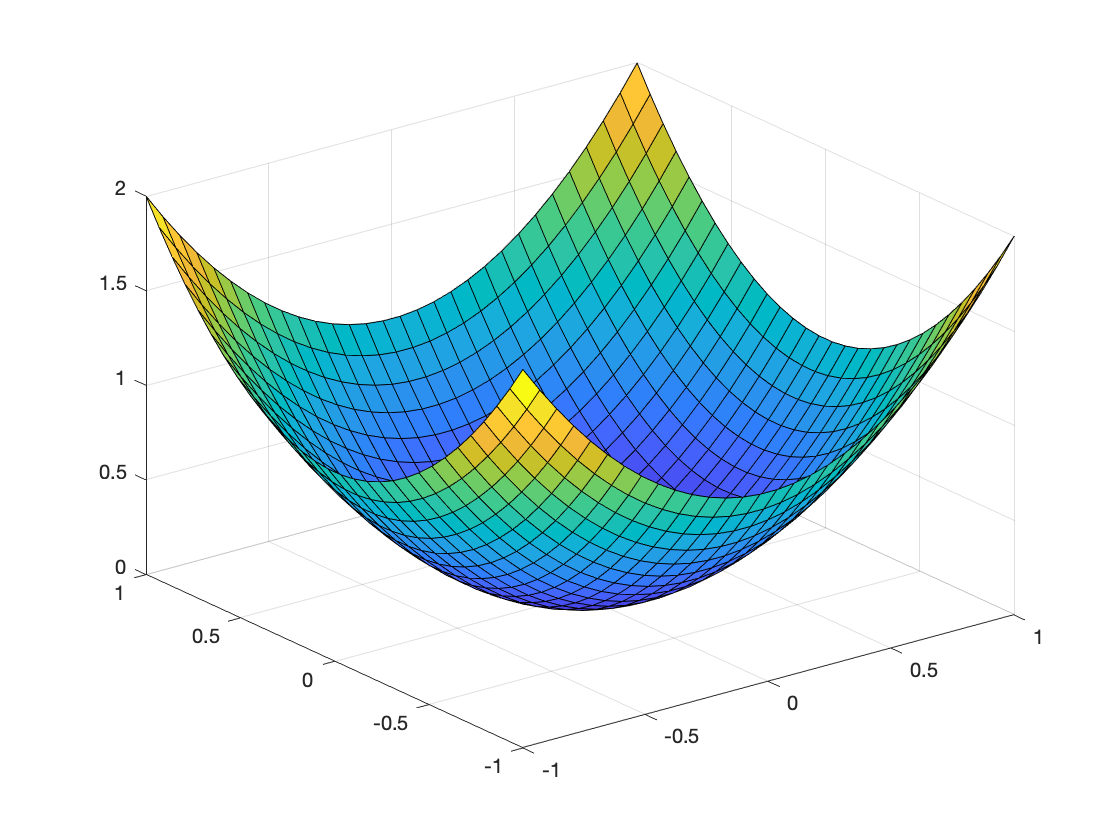

x = linspace(-1, 1, 30);
y = x;
[X, Y] = meshgrid(x, y);
Z = f(X, Y);

surf(X, Y, Z)

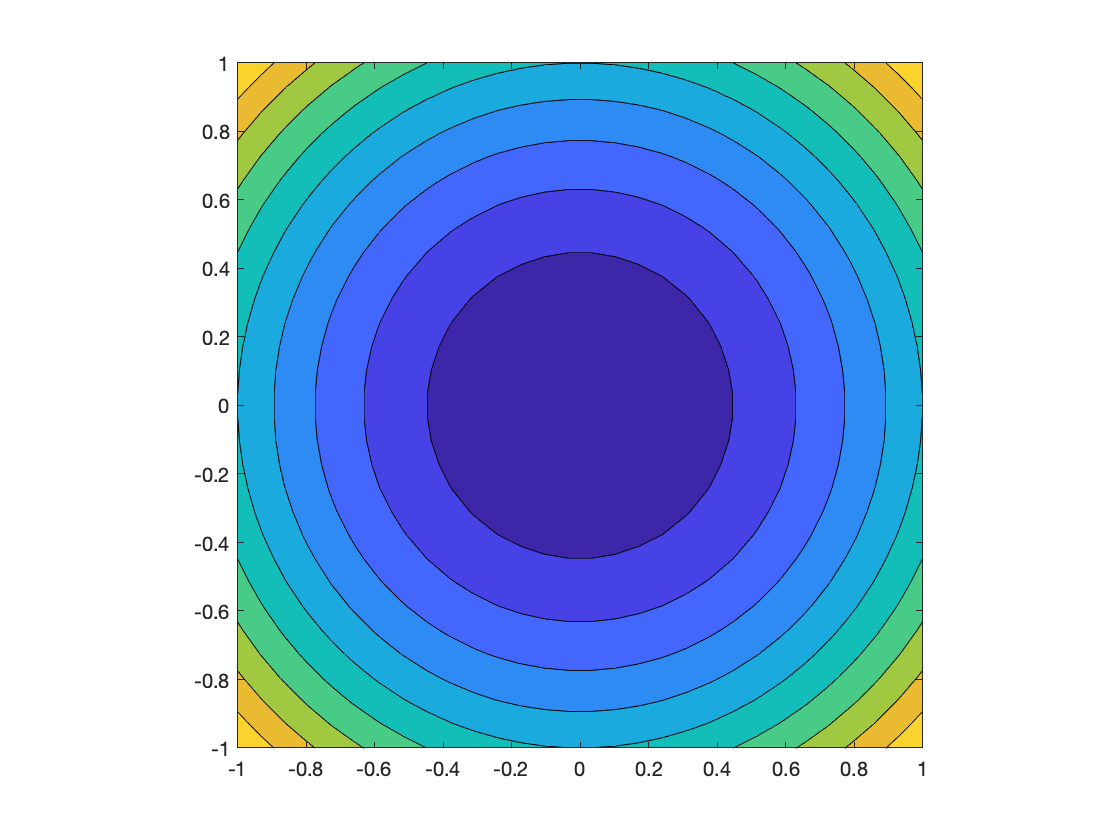

contourf(X, Y, Z)
axis equal

Plot Gradient

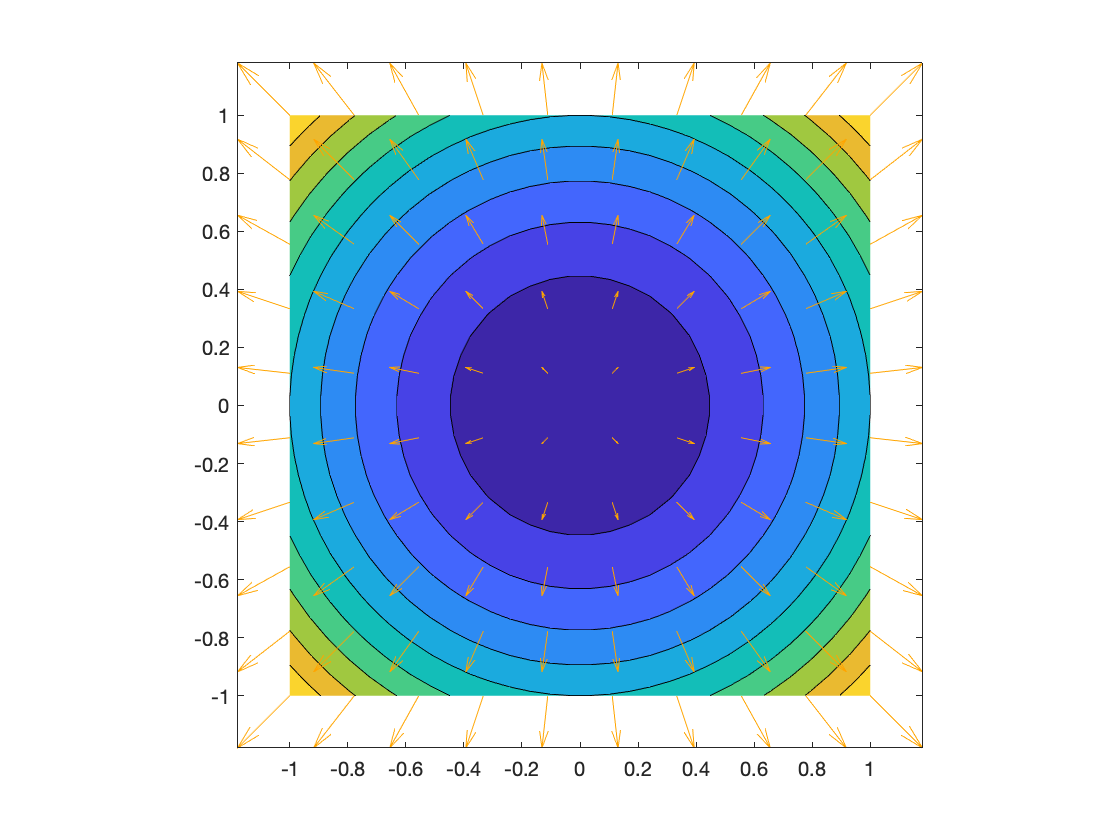

gradFX = @(x, y) 2 * x;
gradFY = @(x, y) 2 * y;
xG = linspace(-1, 1, 10);
yG = xG;
[XG, YG] = meshgrid(xG, yG);
uX = gradFX(XG, YG);
uY = gradFY(XG, YG);

contourf(X, Y, Z)
hold on
quiver(XG, YG, uX, uY, 'color', [255,165,0]/255)
axis equal
hold off

## Vector fields

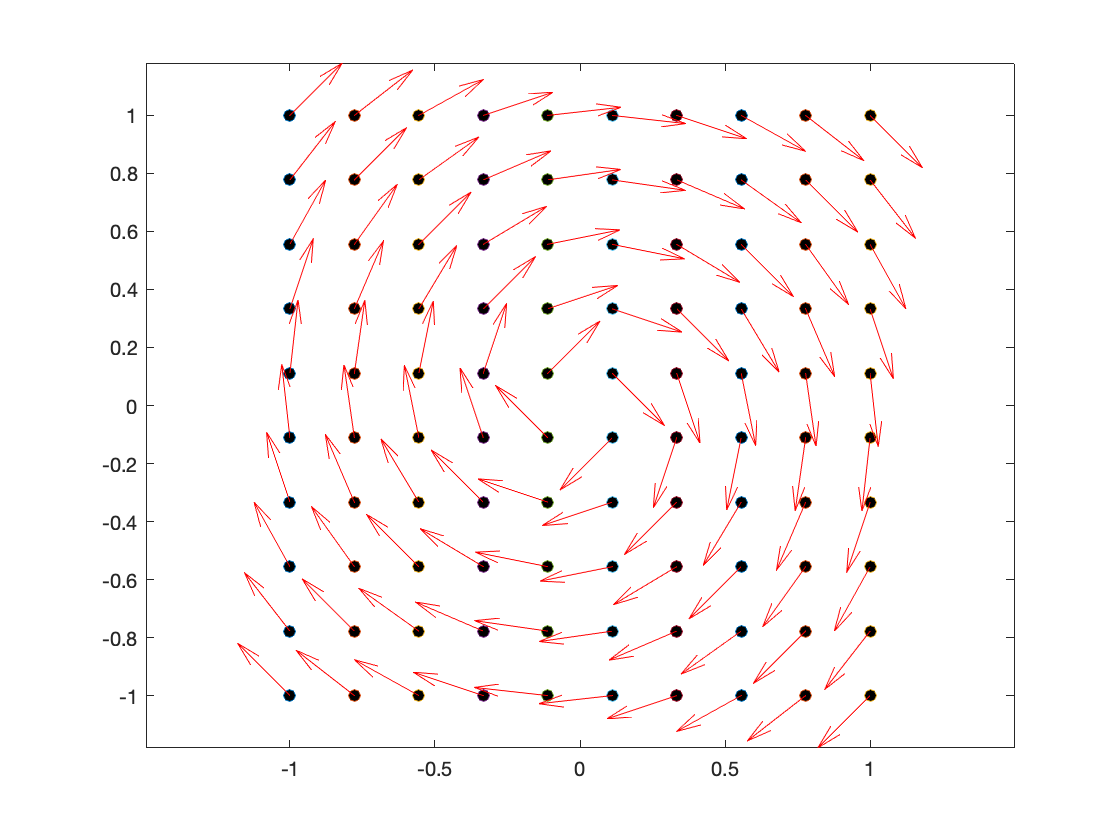

vx = @(x, y)  1 ./ hypot(x, y) .* y;
vy = @(x, y) -1 ./ hypot(x, y) .* x;
x = linspace(-1, 1, 10);
y = x;
[X, Y] = meshgrid(x, y);
ax = vx(X, Y);
ay = vy(X, Y);
plot(X, Y, 'o', 'MarkerFaceColor','k')
hold on
quiver(X, Y, ax, ay, 'color', 'red')
hold off
axis equal